fs=10000 %% sampling frequency

fs = 10000

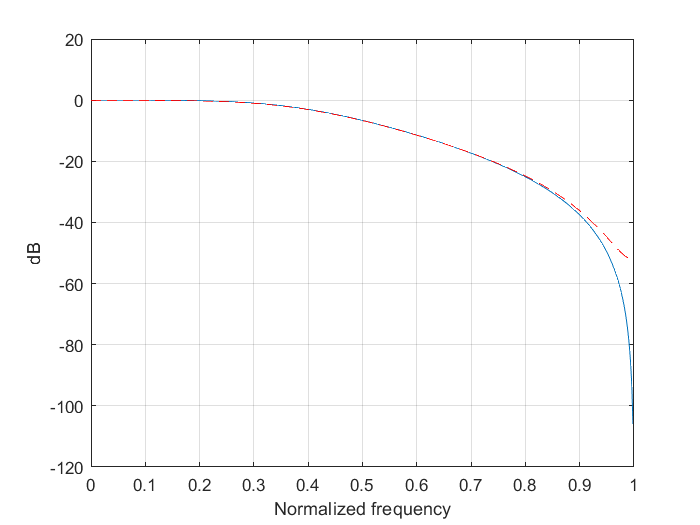

bi =     52   105    52


ai =    256   -95    50


bq =     0.2031    0.4102    0.2031


aq =     1.0000   -0.3711    0.1953


f1=500;  %% first sinewave freq (in band)
f2=4500; %% second sinnewave freq (out band)

N=2; %% filter order
nb=9; %% number of bits

T=1/500; %% maximum period
tt=0:1/fs:10*T; %% time samples

x1=sin(2*pi*f1*tt); %% first sinewave
x2=sin(2*pi*f2*tt); %% second sinewave

x=(x1+x2)/2; %% input signal

[bi, ai, bq, aq]=myiir_design(N, nb) %% filter design


y=filter(bq, aq, x); %% apply filter

## plots

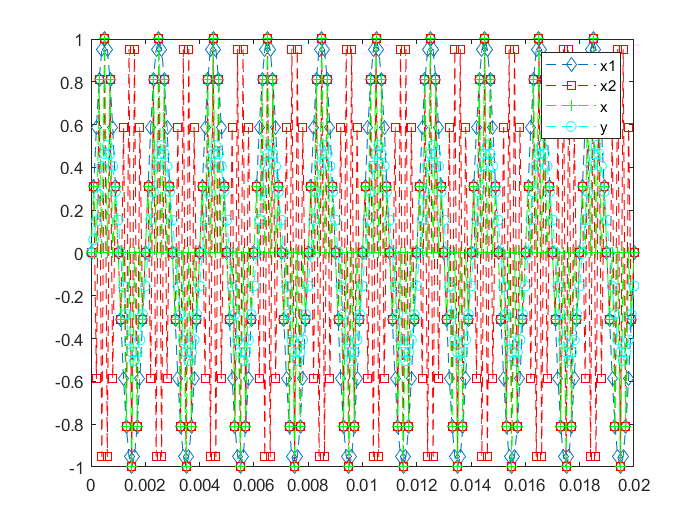

figure
plot(tt,x1,'--d');
hold on
plot(tt,x2,'r--s');
plot(tt,x, 'g--+');
plot(tt, y, 'c--o');

legend('x1', 'x2', 'x', 'y')

## quantize input and output

xq=floor(x*2^(nb-1));
idx=find(xq==2^(nb-1));
xq(idx)=2^(nb-1)-1;

yq=floor(y*2^(nb-1));
idy=find(yq==2^(nb-1));
yq(idy)=2^(nb-1)-1;

## save input and output

fp=fopen('samples.txt','w');
fprintf(fp,'%d\n', xq);
fclose(fp);

fp=fopen('resultsm.txt', 'w');
fprintf(fp, '%d\n', yq);
fclose(fp);